%function KE=cal_KE(uu,vv)

uu=u.unstag(:,:,10); vv=v.unstag(:,:,10);

   %--- calculate 2-D KE sprectral for 2-D matrix u, v
   
   [nx, ny]=size(uu);

   ufft=fft2(uu);
   vfft=fft2(vv);
   
   KE=abs(ufft) + abs(vfft);
   
   KE(1,1)=0;
   KEshi=fftshift(KE);
   
   
   
   cenx=ceil((nx+1)/2);  ceny=ceil((ny+1)/2);
   
   nk=zeros(nx,ny);
   
   for xi=1:nx
     for yi=1:ny
          nk(xi,yi)=((xi-cenx)^2+(yi-ceny)^2)^0.5;        
     end    
   end
   
   nk2=round(nk);

%end

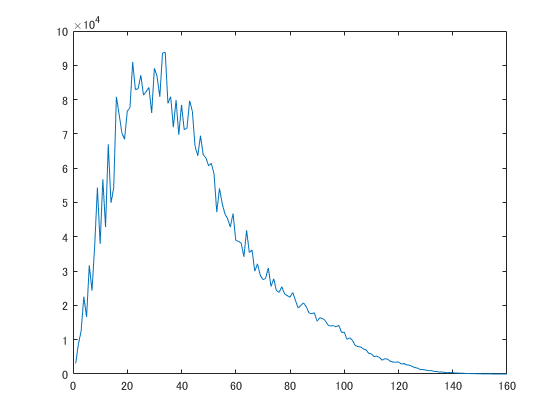

KE_kh=zeros(max(max(nk2)),1);
    for ki=1:max(max(nk2))   
      KE_kh(ki)=sum(KEshi(nk2==ki));   % sum of different kx, ky to kh bin, for each member      
    end
figure
plot(KE_kh)

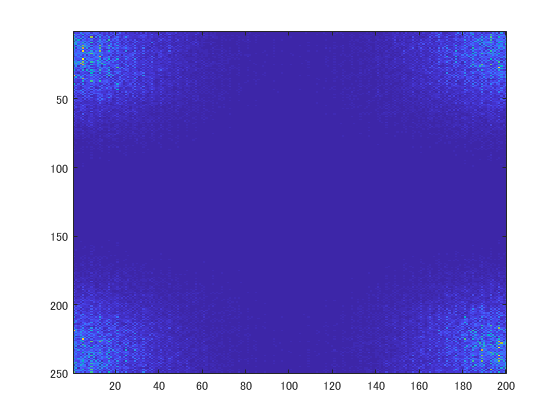



figure
imagesc(KE)

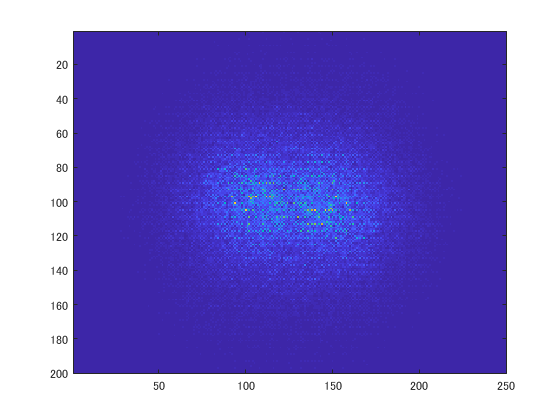


figure
imagesc(KEshi')


figure
imagesc(nk2')